# Lab 02

# Name: M. Shees Abbas (ma11212)

## task 1

### a)

x = 15.5 + 3.175i;

real(x)

ans = 15.5000

imag(x)

ans = 3.1750

conj(x)

ans = 15.5000 - 3.1750i

abs(x)

ans = 15.8218

angle(x)

ans = 0.2020

### b)

[a,b] = pol2cart(pi/4,5);
y = a+(b)*1i;
real(y)

ans = 3.5355

imag(y)

ans = 3.5355

conj(y)

ans = 3.5355 - 3.5355i

abs(y)

ans = 5

angle(y)

ans = 0.7854

## task 2

### a)

#### Try 1

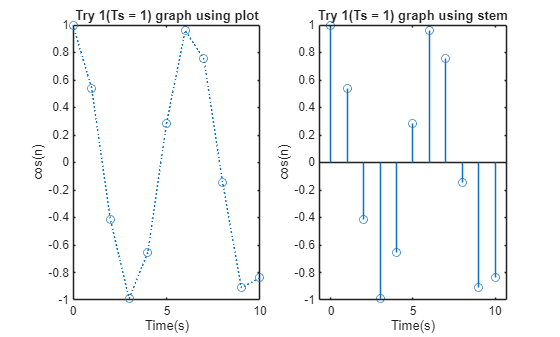

n = 0:10; % Discrete-time n is defined which goes from 0 to 10 in unitysampling interval.
y = cos(n); % A sinusoidal function y[n] is defined attaining values −𝟏 ≤𝒚[𝒏] ≤ 𝟏.
subplot 121; plot(n, y, ':o'); % A continuous-time graphical plot of the signal y[n] where circular markers are used to represent values connected with a dotted line.
title('Try 1(Ts = 1) graph using plot');
xlabel('Time(s)'); ylabel('cos(n)');
subplot 122; stem(n, y); % A more appropriate discrete-time graphical representation.
title('Try 1(Ts = 1) graph using stem');
xlabel('Time(s)'); ylabel('cos(n)');

#### Try 2

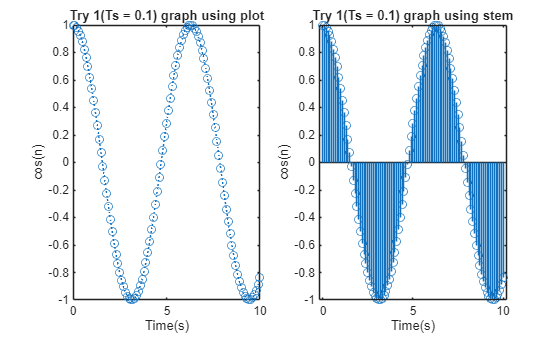

Ts = 0.1; % Defining sampling time, the time interval between twoconsecutive samples
Fs = 1/Ts; % Defining sampling frequency, the number of samples per second
t = 0:Ts:10; % Defining time span
y = cos(t); % Obtaining a discrete-time signal
figure; % Using subplots to depict two plots in one figure
subplot 121; plot(t, y, ':o');
title('Try 1(Ts = 0.1) graph using plot');
xlabel('Time(s)'); ylabel('cos(n)');
subplot 122; stem(t, y);
title('Try 1(Ts = 0.1) graph using stem');
xlabel('Time(s)'); ylabel('cos(n)');

As we make the sampling time smaller **we got better and more clear image** of the sinosoidal graph 

**the difference between plot and stem was that** in **Plot** it makes a continuous graph and then mark a point after each interval of Ts and in **Stem **it only a vertical like of the lenght of Y at after each interval of Ts

### b)

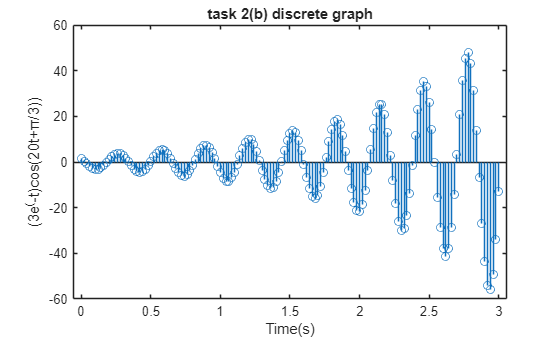

Fs = 50;
Ts = 1/Fs;
t = 0:Ts:3;
x = 3.*exp(t).*cos(20.*t+pi/3);
figure;
stem (t, x);
title('task 2(b) discrete graph');
xlabel('Time(s)'); ylabel('(3e^(-t)cos(20t+π/3))');

#### Try 3

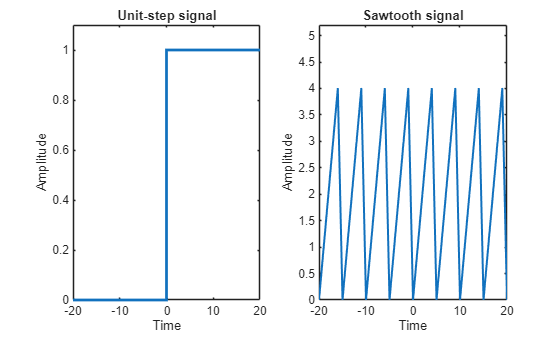

t = -20:1:20;
y = mod(t,5); %the time vector is divided by 5 and remainder is used to plot the values resulting in a sawooth wave when plotted w.r.t time, whereas the second argument 5 represents the time period/duration of one sawtooth pulse
z = (t>=0); % t>=0 returns logic '1' or '0'
subplot(1,2,1);
stairs(t,z,'linewidth',2)				
title('Unit-step signal');
xlabel('Time');
ylabel('Amplitude');				
axis([-20 20 0 1.1]);
subplot(1,2,2);				
plot(t,y,'linewidth',1.5)
title('Sawtooth signal');
xlabel('Time');
ylabel('Amplitude');
axis([-20 20 0 5.2])	

**mod(t,x) : ** it divided the t by x and then return the ramainder of that

**stairs(t,z,'linewidth',2): **it take a time array t and then take a binary array consisting of 1 and 0 then for the graph z(t) whenever value of z be high it will make a vertical step at that point t

**axis(a,b,c,d):** is used to limit the axis of graph where x axis would be limited from a to b and y axis would be limited from c to d

## task 3

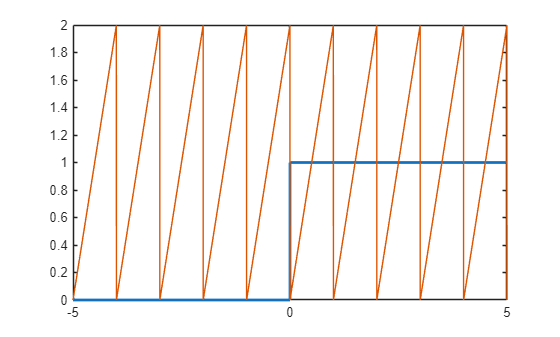

clc;clear
figure;
t = -20:1/1000:20;
z = (t>=0);
stairs(t,z,'linewidth',2)
hold on
x = sawtooth(2*pi*1*t,1)+1;
plot(t,x)
axis([-5 5 0 2]);
hold off

## task 4

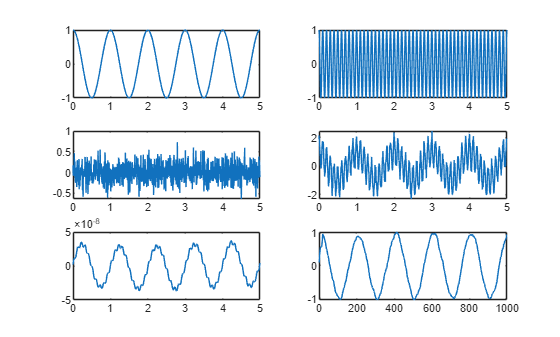

t = 0:0.005:5;
xt1 = cos(2*pi.*t);
xt2 = cos(20*pi.*t);
l = length(xt2);
noise = randn(1,l);
yt = xt1 + xt2 + 0.2.*noise;

subplot (3,2,1);
plot(t,xt1)
subplot (3,2,2);
plot(t,xt2)
subplot(3,2,3);
plot(t,0.2*noise)
subplot(3,2,4);
plot(t,yt)
subplot(3,2,5);
zt = filter(ones(1,5)/5,1,yt);
plot(t,zt)
subplot(3,2, 6);
zt = filter(ones(1,20)/20,1,yt);
plot(zt)

so we first added the the xt1 xt2 and noise signals together then we applied the builtin filter funtion inside the matlab and put sample size to be 5 but the sample size was too small so the wave didnt filter correctly thats why we increased the filter size to be 20 at which the wave filtered correctly